addpath('functions/');

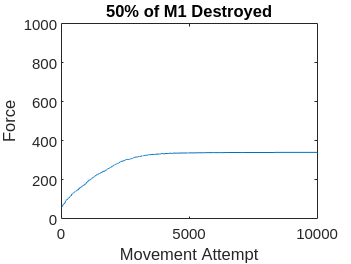

% Creating n Corticalspinal cells
n = 1000; 

% Initalize the base CS cells
% 80% of the n Cortical cells are M1
m1_count = n * 0.8;
m1_destroyed = m1_count * 0.5;
m1_alive = m1_count * 0.5;
m1 = [zeros(1, m1_destroyed), rand(1, m1_alive)];
% 20& of the n Cortical cells are SMA
sma_count = n * 0.2;
sma = rand(1, sma_count);

x_0 = [m1, sma];

% Parameters for zero-mean normal distribution
std_dev = 0.02;
mean = 0;

% CS extensor and flexor connection weights
flexor_c_w = create_cs(0.7, n); 
extensor_c_w = create_cs(0.3, n); 

% Translating MN pool to force
delta = 1;

f_fs = [];
f_es = [];
sma = [];
m1 = [];
final_forces = [];
trials = [];
f_final_net = 0;
max_trials = 10000;
for trial = 1:max_trials
    v_i = std_dev.*randn(1, n) + mean;
    x_i = x_0 + v_i;

    for i = 1:m1_destroyed
        % Ensure CS M1 cells are destroyed (0)
        x_i(i) = 0;
    end

    % Activations
    m1_activation = 0;
    sma_activation = 0;

    % Flexor MN Pools translated to force
    s_fi = 0;
    for i = 1:n
        if i > 0.8 * n
            % SMA
            temp = 0.1 * g_i(x_i(i), flexor_c_w(i));
            sma_activation = sma_activation + temp;
            s_fi = s_fi + temp;
        else
            % M1
            temp = g_i(x_i(i), flexor_c_w(i));
            m1_activation = m1_activation + temp;
            s_fi = s_fi + temp;
        end
    end
    f_f = delta * s_fi;
    
    % Extensor MN Pools translated to force
    s_ei = 0;
    for i = 1:n
        if i > 0.8 * n
            % SMA
            temp = 0.1 * g_i(x_i(i), extensor_c_w(i));
            s_ei = s_ei + temp;
        else
            % M1
            temp = g_i(x_i(i), extensor_c_w(i));
            s_ei = s_ei + temp;
        end
    end
    f_e = delta * s_ei;

    % Net force
    f_net = f_f - f_e;

    if f_net > f_final_net
        f_final_net = f_net;
        x_0 = x_i;
    end

    sma = [sma, sum(x_0(1:m1_count))];
    m1 = [m1, sum(x_0(m1_count+1:n))];
    trials = [trials, trial];
    final_forces = [final_forces, f_final_net];
end

plot(trials, final_forces)
title("50% of M1 Destroyed")
ylim([0, n])
ylabel('Force')
xlabel('Movement Attempt')

saveas(gcf,'images/M1Destroyed50.png')

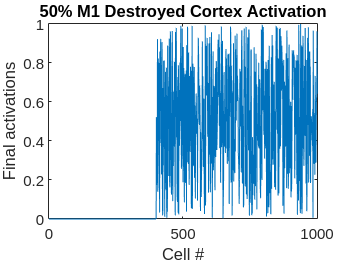

plot(x_0)
%hold on
%plot(10 * ones(1, m1_count))
%hold off
title("50% M1 Destroyed Cortex Activation")
%ylim([0, 15])
ylabel("Final activations")
xlabel("Cell #")

saveas(gcf, 'images/M1Destroyed50Activations.png')

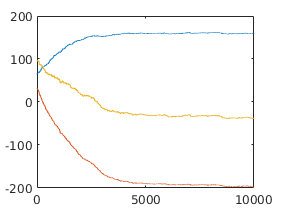

plot([1:10000], f_fs, [1:10000], f_es, [1:10000], f_fs + f_es)

plot(sma)

plot(m1)